## Интерполирванные результаты

Кубическая интерполяция

load("Srfc.mat","Srfc");

Задание начальных параметров для поиска

% Задание требуемого расхода
Q =3.5

Q = 3.5000

% Задание требуемой частоты
RPM = 10395

RPM = 10395

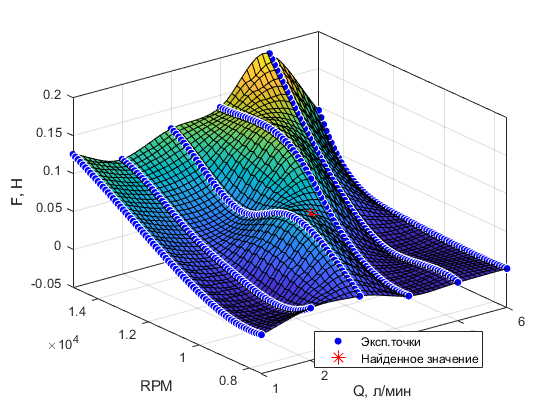

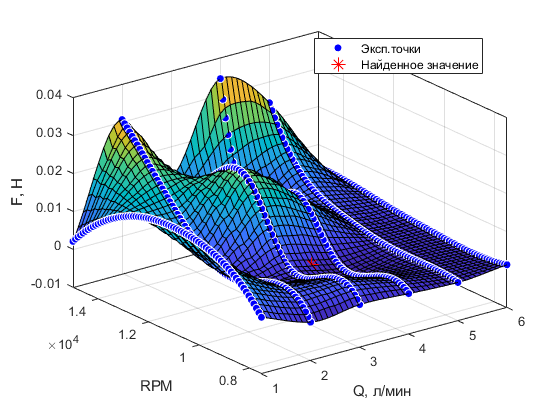

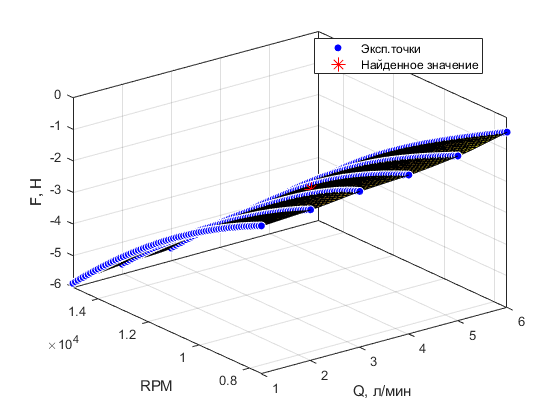

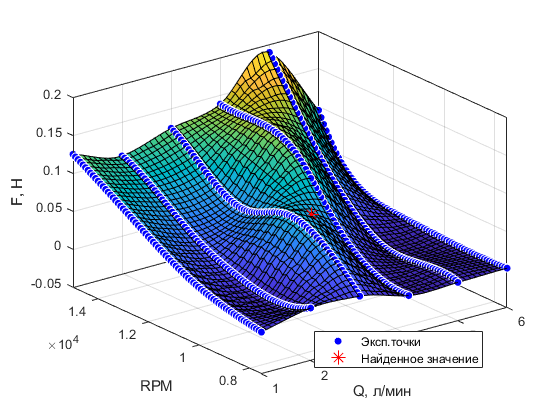

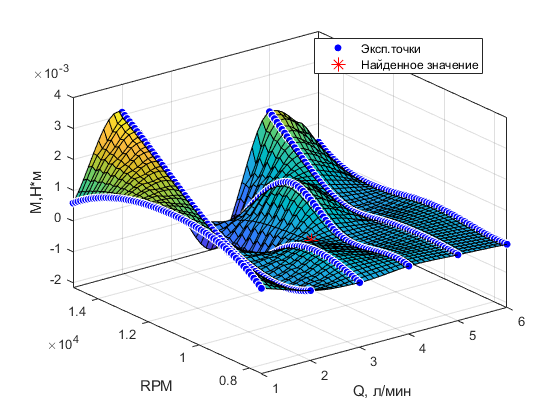

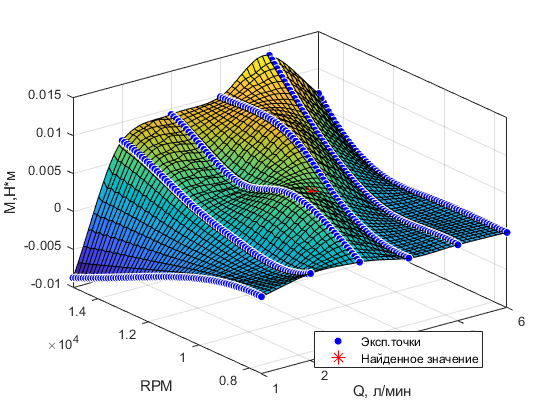

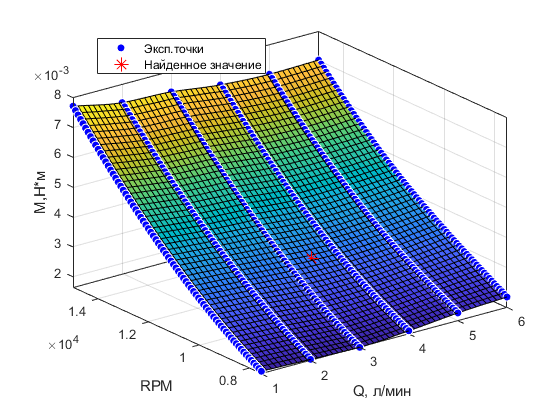

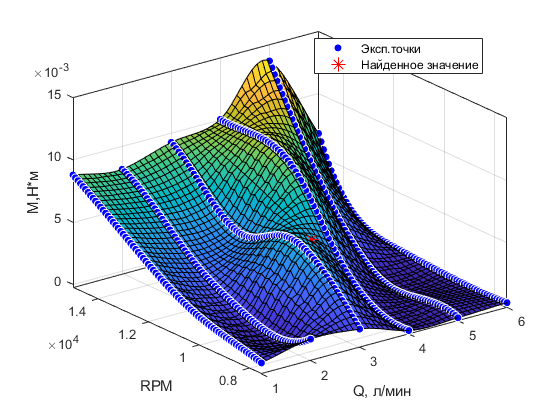

% Функции для получения значений всех сил и моментов в
% зависимости от требуемого расхода и частоты
Fit = findPoint(Srfc,Q,RPM);

Вывод результатов

F.x = Fit(1).F;
F.y = Fit(2).F;
F.z = Fit(3).F;
F.r = Fit(4).F;
M.x = Fit(5).M;
M.y = Fit(6).M;
M.z = Fit(7).M;
M.r = Fit(8).M;
formatSpec = 'Расход: %4.2f л/мин, частота: %4.0f об/мин\n';
fprintf(formatSpec,Q,RPM)

Расход: 3.50 л/мин, частота: 10395 об/мин


for idx = 1:4
    if idx == 1
        name = 'Fx';
    end
    if idx == 2
        name = 'Fy';
    end
    if idx == 3
        name = 'Fz';
    end
    if idx == 4
        name = 'Fr';
    end
    formatSpec = 'Сила %s = %4.4f Н\n';
    fprintf(formatSpec,name,Fit(idx).F);
%     Fit.(sprintf('F%d',idx))
end

Сила Fx = 0.0720 Н
Сила Fy = 0.0013 Н
Сила Fz = -2.2801 Н
Сила Fr = 0.0719 Н


for idx = 5:8
    if idx == 5
        name = 'Mx';
    end
    if idx == 6
        name = 'My';
    end
    if idx == 7
        name = 'Mz';
    end
    if idx == 8
        name = 'Mr';
    end
    formatSpec ='Момент %s = %4.4f Н*м\n';
    fprintf(formatSpec,name,Fit(idx).M);
end

Момент Mx = 0.0000 Н*м
Момент My = 0.0052 Н*м
Момент Mz = 0.0033 Н*м
Момент Mr = 0.0052 Н*м


Функция для поиска точки на интерполированной поверхности

function [Fit] = findPoint(Srfc,Q_to_find,RPM_to_find)
% m = 1 - Fx, m=2 - Fy, m=3 - Fz, m=4 - Fr, m=5 - Mx и т.д. m=8 - Mr
for m = 1:8
    
    xData = Srfc(m).x;
    yData = Srfc(m).y;
    zData = Srfc(m).z;
    f = Srfc(m).f;
    
    % find point    
    figure('Name',"Интерполяция");
    point_Z = feval(f,Q_to_find,RPM_to_find);
  
    title('Интерполяция (кубич)');
    plot( f, [xData, yData],zData)
    hold on
    plot3(Q_to_find,RPM_to_find,point_Z,"r*",'MarkerSize',10)
   
    xlabel('Q, л/мин')
    ylabel('RPM')
        if m<=4
            zlabel('F, Н')
        else
            zlabel('М,Н*м') 
        end
    legend('Эксп.точки','Найденное значение', 'Location', 'best', 'Interpreter', 'none' )
    hold off
    
    % Get Moment or Force values from model
    %     z2=f(xData,yData)
    if m<5
        Fit(m).F=f(Q_to_find,RPM_to_find);
    else
        Fit(m).M=f(Q_to_find,RPM_to_find);
    end

end
end
